## Task 1

cell_colony_image = imread("data/Cell_Colony.jpg");
cell_colony_image_size = size(cell_colony_image)

cell_colony_image_size =    408   406


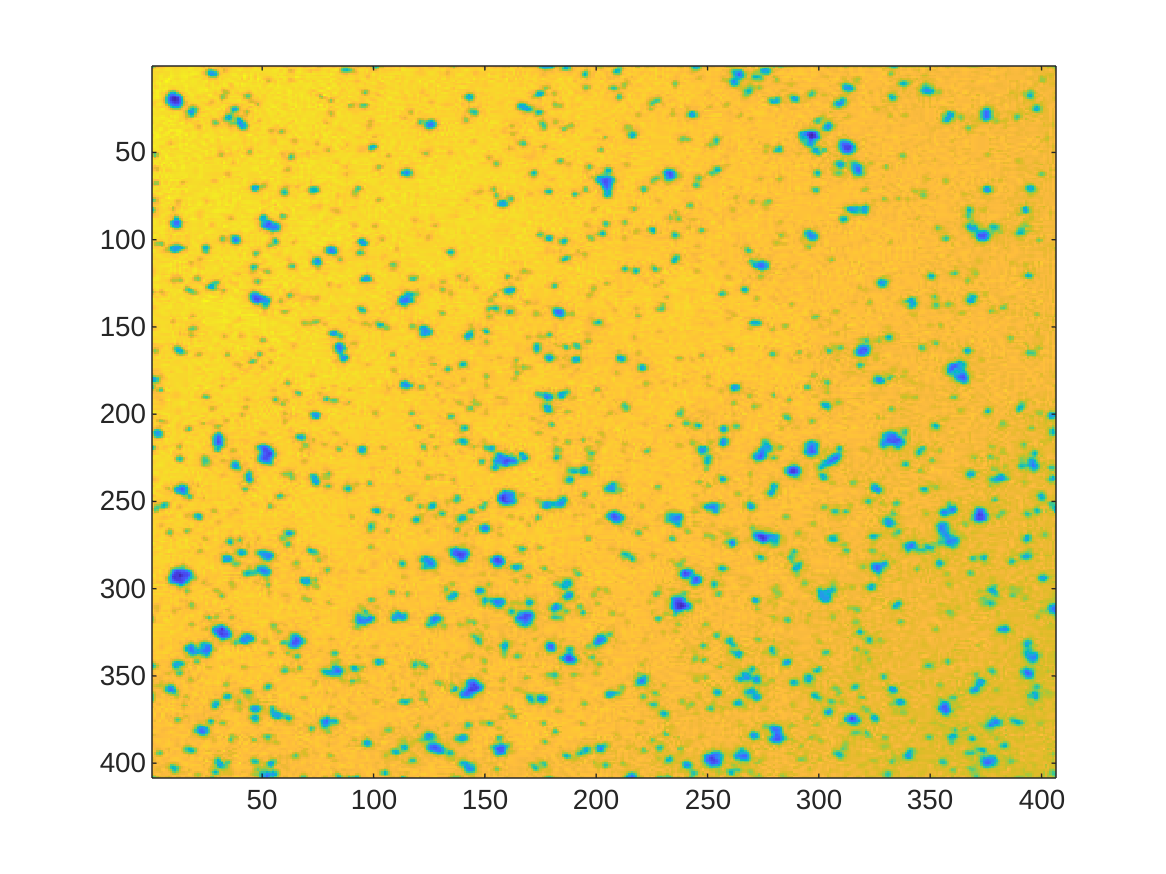

figure = figure();
imagesc(cell_colony_image);

## Task 2

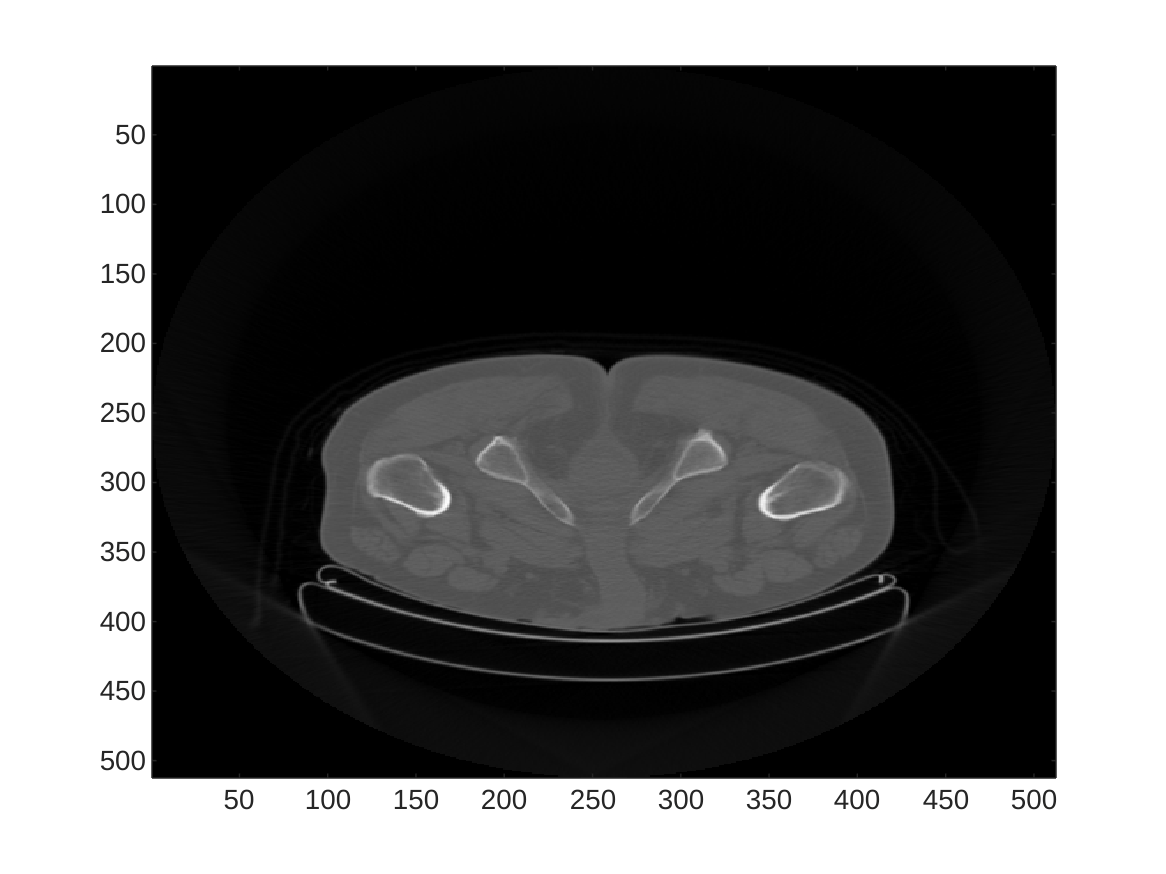


img_00058 = dicomread("data/IMG00058");
img_0058_info = dicominfo("data/IMG00058");
figure();
imagesc(img_00058);
colormap("gray");

## Task 3

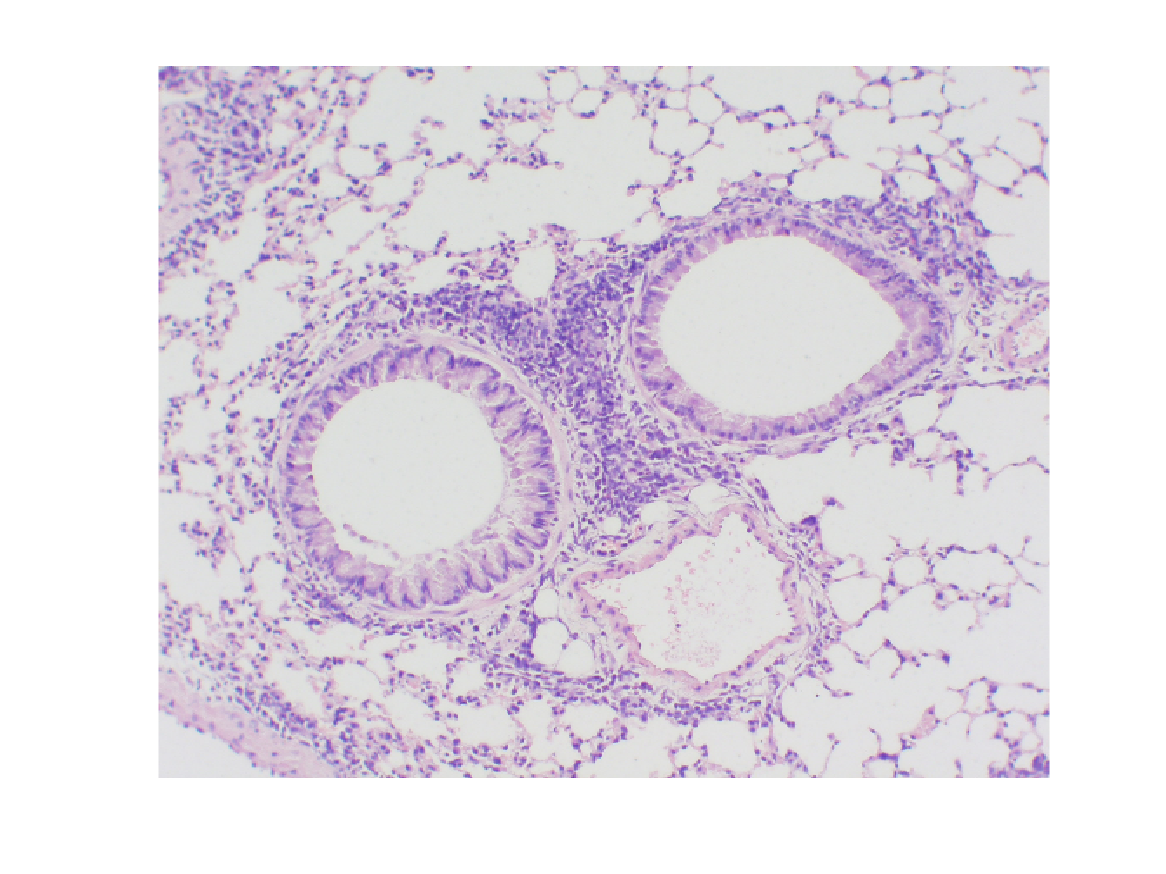


salino_10_image = imread("data/O_3_44Salino10X_1.BMP");
figure();
imshow(salino_10_image(:,:,:));

whos("salino_10_image")

  Name                    Size                  Bytes  Class    Attributes

  salino_10_image      1368x1712x3            7026048  uint8              



## Task 4

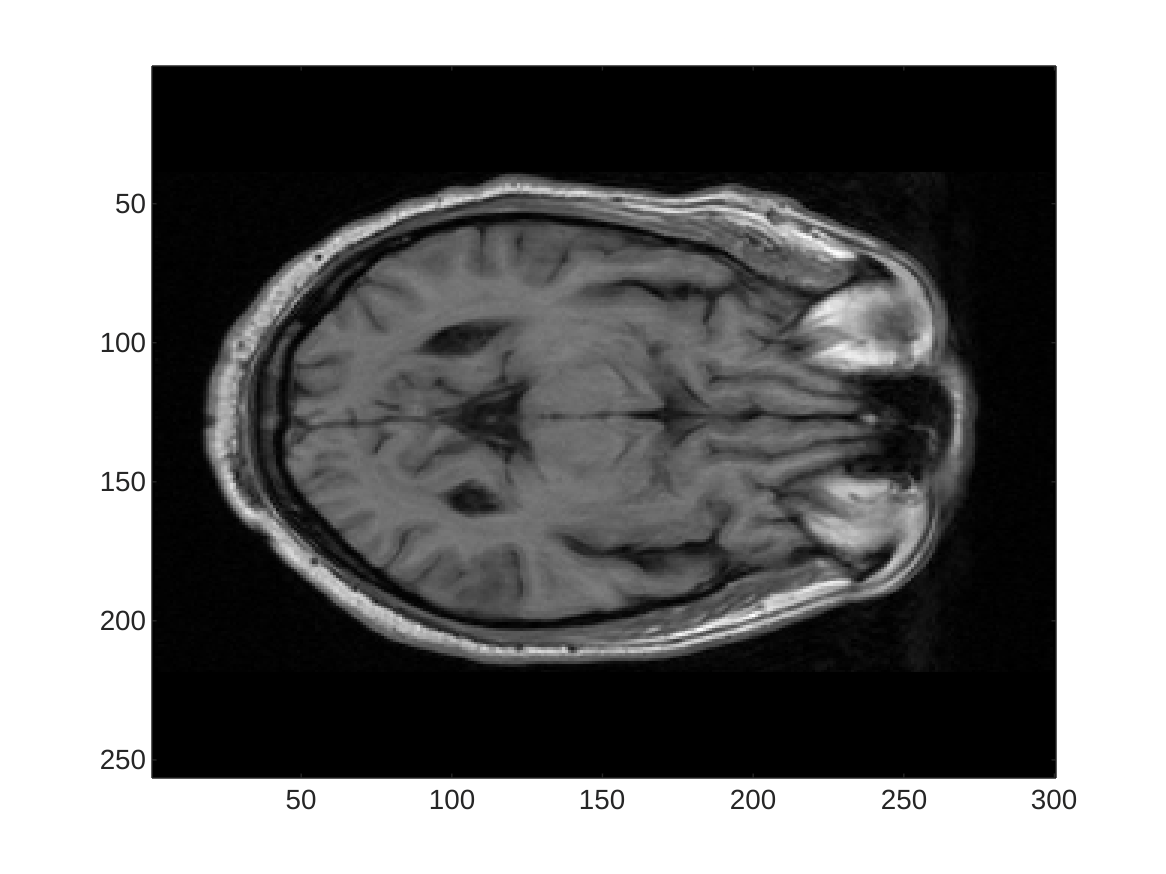

rm1_slice = fread(fopen("data/RM_1slice.raw"), [256, 300], 'int16', 'ieee-le');
figure();
imagesc(rm1_slice);
colormap(gray);

whos("rm1_slice")

  Name             Size              Bytes  Class     Attributes

  rm1_slice      256x300            614400  double              



## Task 5

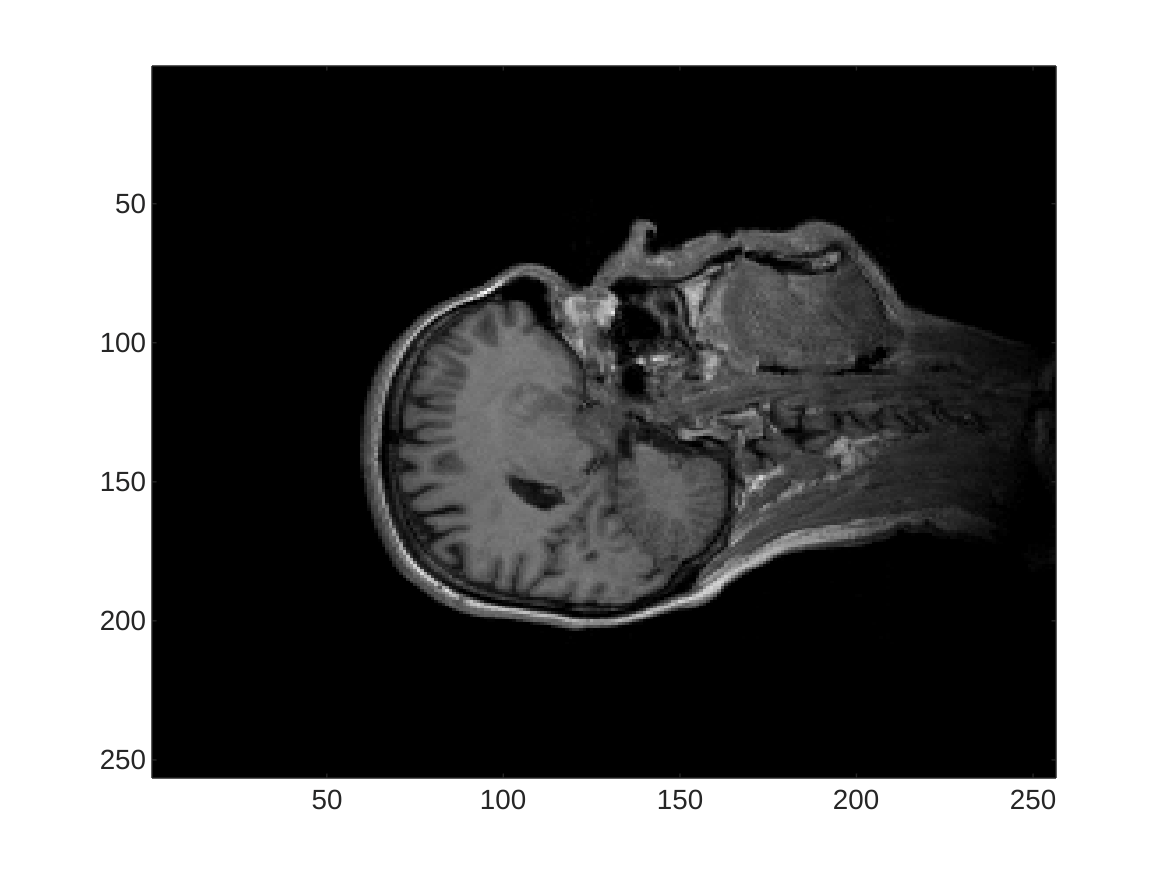


t1_head_1_image = fread(fopen("data/t1-head/t1-head_1.raw", "r"), [256, 256], "int16", "ieee-le");
figure();
imagesc(t1_head_1_image);
colormap(gray);

whos("t1_head_1_image")

  Name                   Size              Bytes  Class     Attributes

  t1_head_1_image      256x256            524288  double              



num_slices = 40

num_slices = 40

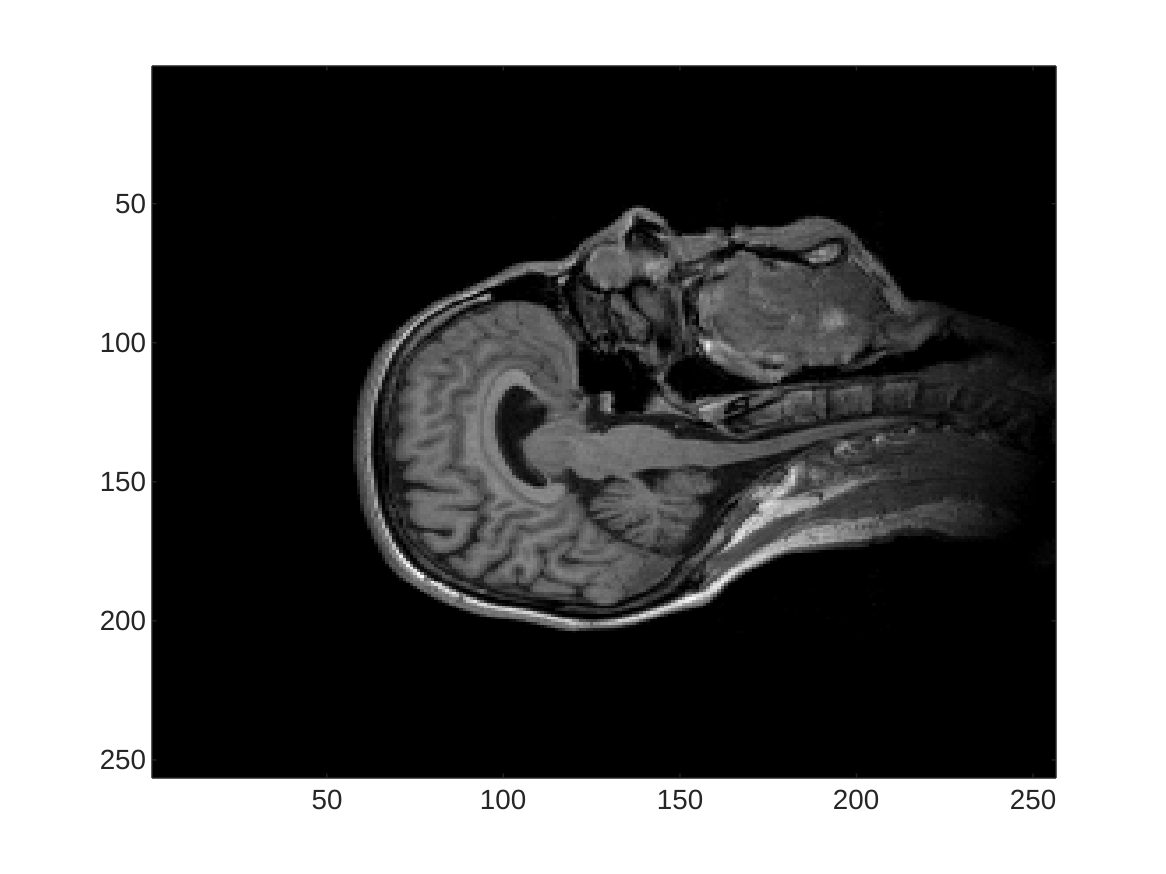

head_3d = zeros(num_slices, 256, 256);
for i = 1:40
    head_slice = fread(fopen("data/t1-head/t1-head_" + i + ".raw", "r"), [256, 256], "int16", "ieee-le");
    head_3d(i,:,:) = head_slice;
end

example_slice = squeeze(head_3d(20, :, :));
figure();
imagesc(example_slice);

head_3d_file = strcat("result/head_3d_", num2str(size(head_3d, 1)), "_slices.raw");
head_3d_file_output = fopen(head_3d_file, "w");
fwrite(head_3d_file_output, head_3d, "int16");
fclose(head_3d_file_output);